# Laboratory exercises: continuous-time speed control of a DC motor

Riccardo Antonello ([antonello@dei.unipd.it](mailto:antonello@dei.unipd.it)) and Luca Schenato ([schenato@dei.unipd.it](mailto:schenato@dei.unipd.it))

March 25, 2021

Dept. of Information Engineering, University of Padova, Italy

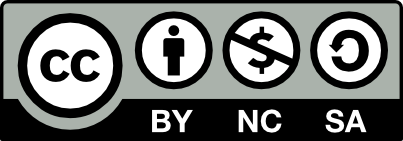

*This work is licensed under a Creative Commons Attribution-NonCommercial-ShareAlike 4.0 International license.*

## Exercise 3: simulation of a continuous-time speed control system for a DC motor using Simulink

Reconsider the continuous-time speed control system of exercise 2. By using Simulink, do the following points:

1) Implement a Simulink model of the speed control system, with the continuous-time P controller found in point 2 of exercise 2.

Simulate the model with an appropriate solver (either variable-step, or fixed-step with a suitable step), by considering a step speed reference $\omega^*(t)$ of amplitude $A_\omega = 300\,\mathrm{rpm}$ applied at $t_\omega = 0.1\,\mathrm{s}$, and a disturbance $d(t)$ of amplitude $A_d = -3\,\mathrm{V}$ applied at $t_d = 0.5\,\mathrm{s}$.

On a MATLAB figure, plot the following signals:

- *plot 1*: actual speed $\omega(t)$, measured speed $\omega_m(t)$, speed reference $\omega^*(t)$, all in $\mathrm{[rpm]}$ units..

- *plot 2*: voltage command $u(t)\,\mathrm{[V]}$.

Does the P controller guarantee perfect rejection of the constant disturbance $d(t)$ ?

*Solution*.

%   conversion gains
rads2rpm = 60/2/pi;
rpm2rads = 2*pi/60;

%   DC motor data
mot.k = 5.2;            %   static gain
mot.T = 0.03;           %   dominant time constant

%   speed filter data
fc = 50;            %   cut-off freq
wc = 2*pi*fc;
dc = 1/sqrt(2);     %   damping factor

wfilt.num = [wc^2, 0];
wfilt.den = [1, 2*dc*wc, wc^2];

%   speed PI controller data
wctrl.kp = 0.7442;      %   proportional gain
wctrl.ki = 0;           %   integral gain

%   speed ref
wref.A = 300;           %   step amplitude [rpm]
wref.t0 = 0.1;          %   step time [s]

%   load disturbance
dist.A = -3;            %   step amplitude [rpm]
dist.t0 = 0.4;          %   step time [s]

%   open simulink model   
open_system('speed_ctrl_1.slx');

Run simulation:

%   set simulation params
set_param('speed_ctrl_1', ...
    'SolverType', 'Variable-step', ...
    'Solver', 'ode45', ...
    'MaxStep', '0.001', ...
    'StopTime', '1.0');

%   run simulation
sim('speed_ctrl_1');

Plot results:

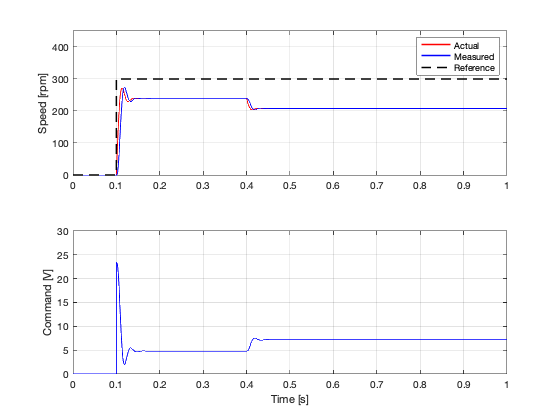

%   extract simulation results
t = simres1.time;                           %   time [s]
wm = simres1.signals(1).values(:,1);        %   actual motor speed [rpm]
wm_meas = simres1.signals(1).values(:,2);   %   measured motor speed [rpm]
wm_ref = simres1.signals(1).values(:,3);    %   motor speed reference [rpm]
u = simres1.signals(2).values(:,1);         %   control command [V]

%   plot control response
figure;
subplot(2, 1, 1);
plot(t, wm, 'r-', 'LineWidth', 1.5);
hold on;
plot(t, wm_meas, 'b-', 'LineWidth', 1.5);
plot(t, wm_ref, 'k--', 'LineWidth', 1.5);
grid on;
ylim([0, 450]);
xlim([0, t(end)]);
ylabel('Speed [rpm]');
legend('Actual', 'Measured', 'Reference');

subplot(2, 1, 2);
plot(t, u, 'b-', 'LineWidth', 1.5);
ylabel('Command [V]')
xlabel('Time [s]');
ylim([0, 30]);
xlim([0, t(end)]);
grid on;

The P controller is unable to perfectly reject the constant load disturbance.

2) Repeat the point 1, by using the PI controller obtained in point 3 of exercise 2.

Does the PI controller guarantee perfect rejection of the constant disturbance $d(t)$ ?

*Solution*.

%   speed PI controller data
wctrl.kp = 0.4429;              %   proportional gain
wctrl.ki = 100 * wctrl.kp;      %   integral gain

%   open simulink model   
open_system('speed_ctrl_1.slx');

Run simulation:

%   run simulation
sim('speed_ctrl_1');

Plot results:

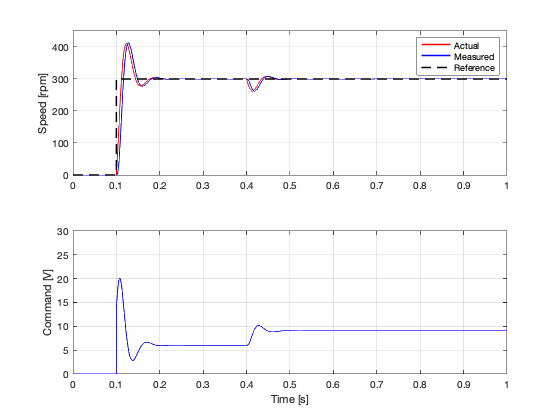

%   extract simulation results
t = simres1.time;                           %   time [s]
wm = simres1.signals(1).values(:,1);        %   actual motor speed [rpm]
wm_meas = simres1.signals(1).values(:,2);   %   measured motor speed [rpm]
wm_ref = simres1.signals(1).values(:,3);    %   motor speed reference [rpm]
u = simres1.signals(2).values(:,1);         %   control command [V]

%   plot control response
figure;
subplot(2, 1, 1);
plot(t, wm, 'r-', 'LineWidth', 1.5);
hold on;
plot(t, wm_meas, 'b-', 'LineWidth', 1.5);
plot(t, wm_ref, 'k--', 'LineWidth', 1.5);
grid on;
ylim([0, 450]);
xlim([0, t(end)]);
ylabel('Speed [rpm]');
legend('Actual', 'Measured', 'Reference');

subplot(2, 1, 2);
plot(t, u, 'b-', 'LineWidth', 1.5);
ylabel('Command [V]')
xlabel('Time [s]');
ylim([0, 30]);
xlim([0, t(end)]);
grid on;

The PI controller guarantees perfect rejection of the constant load disturbance.